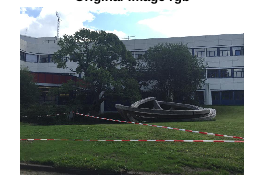

clear  % delete the workspace
clc    % refresh the command window
close all hidden 

% Read Original image and resize the image 
img_1 = imread('/home/srb-jarvis/fh_3dimgprocessing/2. Labtask/6. Lab6_SIFT detector and Optical flow/p5_mensa.jpg');
img_2 = imread('/home/srb-jarvis/fh_3dimgprocessing/2. Labtask/6. Lab6_SIFT detector and Optical flow/p5_mensa_rotated.jpg');
imshow(img_1),title("Original-Image rgb")

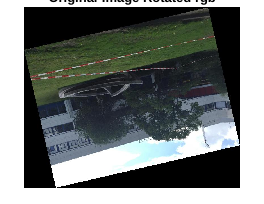

imshow(img_2),title("Original-Image Rotated rgb")

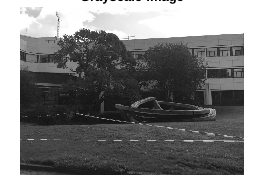

img1_gray = im2gray(img_1);
img2_gray = im2gray(img_2);
imshow(img1_gray),title("Grayscale-Image")

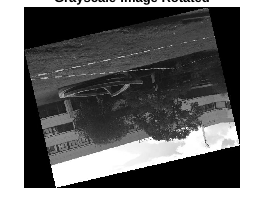

imshow(img2_gray),title("Grayscale-Image Rotated")

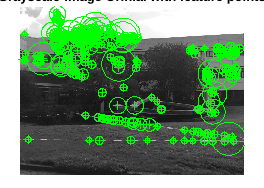

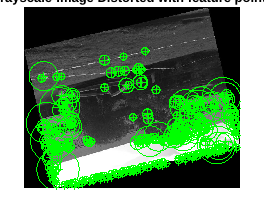

% Detect SIFT features in both images
pointsOriginal = detectSURFFeatures(img1_gray, MetricThreshold=2000);
pointsDistorted = detectSURFFeatures(img2_gray, MetricThreshold=2000);

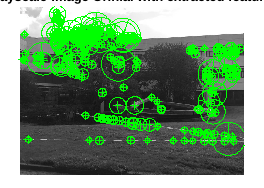

% Extract features and compare the detected blobs in the images 
[featuresOriginal,validPtsOriginal] = extractFeatures(img1_gray,pointsOriginal);
figure;
imshow(img1_gray);
hold on;
plot(validPtsOriginal,showOrientation=true);
title("Grayscale-Image Orinial with extracted features")

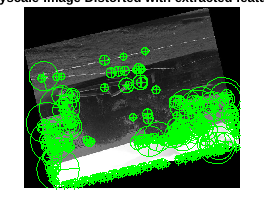


[featuresDistorted,validPtsDistorted] = extractFeatures(img2_gray,pointsDistorted);
figure;
imshow(img2_gray);
hold on;
plot(validPtsDistorted,showOrientation=true);
title("Grayscale-Image Distorted with extracted features")

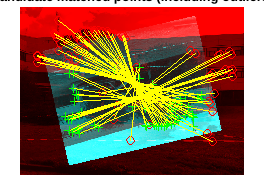

% Finding the matched candidates
indexPairs = matchFeatures(featuresOriginal,featuresDistorted);

% Finding point location in both images 
matchedOriginal = validPtsOriginal(indexPairs(:,1));
matchedDistorted = validPtsDistorted(indexPairs(:,2));

% Display the matched candidates 
figure
showMatchedFeatures(img1_gray,img2_gray,matchedOriginal,matchedDistorted)
title('Candidate matched points (including outliers)')

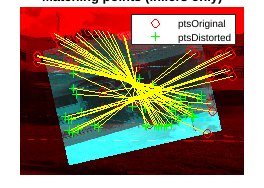


% Determine the transformation from matched points based on similarity
[tform,inlierIdx] = estgeotform2d(matchedDistorted, ...
    matchedOriginal,'similarity');
inlierDistorted = matchedDistorted(inlierIdx,:);
inlierOriginal = matchedOriginal(inlierIdx,:);

figure
showMatchedFeatures(img1_gray, img2_gray,inlierOriginal,inlierDistorted)
title('Matching points (inliers only)')
legend('ptsOriginal','ptsDistorted')

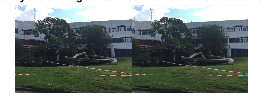


% Trnsform the distorted image back using the transform calculated in the
% preveous step
outputView = imref2d(size(img1_gray));
recovered = imwarp(img_2,tform,OutputView=outputView);

figure
imshowpair(img_1,recovered,'montage')
title("Montage of Original Image and TRnsformed Image")